patternsearch stopped because it exceeded options.MaxIterations.


Iteration 1: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 2: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 3: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 4: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 5: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 6: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 7: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 8: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 9: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 10: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 11: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 12: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 13: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


Iteration 14: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


patternsearch stopped because it exceeded options.MaxIterations.


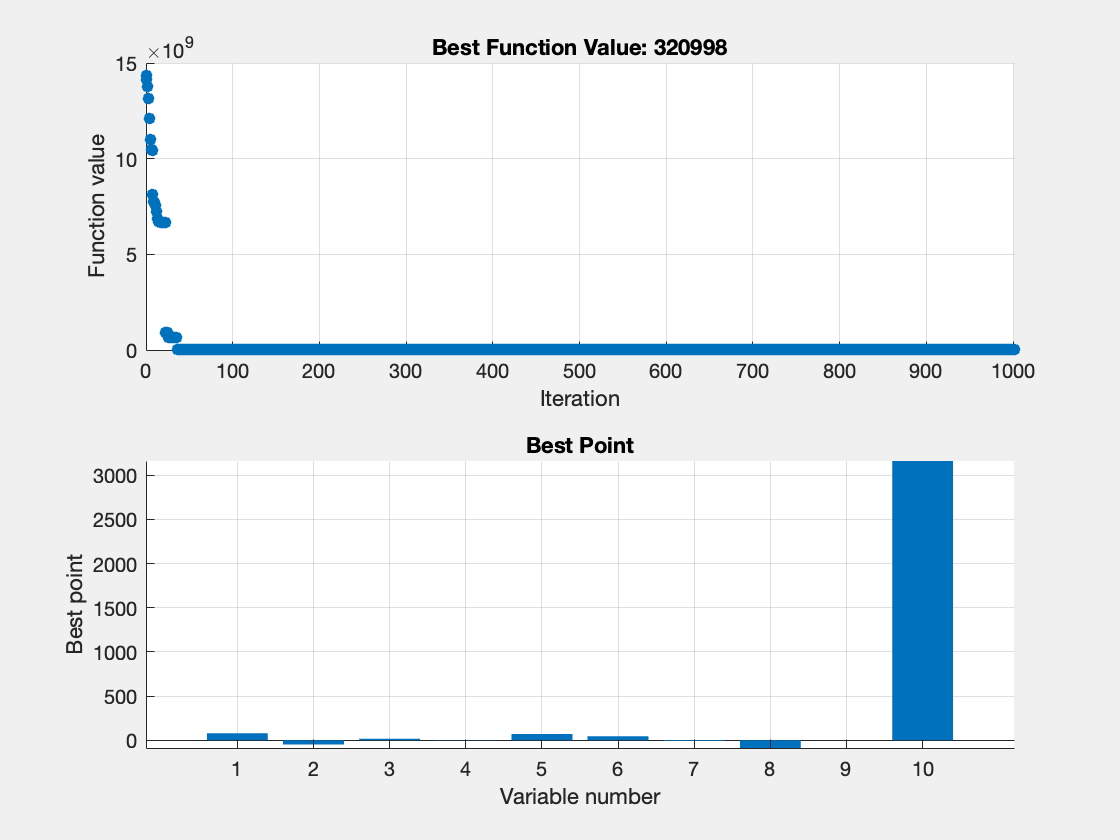

Iteration 15: Exit Flag - 0


   Termination Reason: patternsearch stopped because it exceeded options.MaxIterations.


clc, clear, close all
rng default
global initial_flag
%% Pattern Search Optimization 15 iterations
initial_flag = 0;
options = optimoptions('patternsearch', 'PlotFcn', {@psplotbestf, @psplotbestx});
 
% Initialize variables
ps_main_val = zeros(1, 15);
ps_main_exit_flag = zeros(1, 15);
ps_main_op = zeros(1, 15);
 
for i = 1:15
  initial_flag = 0;
   % Pattern Search for CEC function 6, D=2
   [ps_x, ps_val, ps_exit_flag, ps_output] = patternsearch(@(x) benchmark_func(x, 6), rand(1, 10), [], [], [], [], [], [], options);
  
   % save visualizations to file
   fname = sprintf('filename_ps(%d).fig', i);
  savefig(fname)
 
   % Display information about the optimization process
   disp(['Iteration ', num2str(i), ': Exit Flag - ', num2str(ps_exit_flag)]);
   disp(['   Termination Reason: ', ps_output.message]);
  
   % Store results in arrays
  ps_main_val(i) = ps_val;
  ps_main_exit_flag(i) = ps_exit_flag;
  
   % Check if 'fval' field exists in the output structure
   if isfield(ps_output, 'fval')
      ps_main_op(i) = min(ps_output.fval);
   else
       % If 'fval' doesn't exist, you may need to adjust accordingly
      ps_main_op(i) = NaN;  % or any appropriate default value
   end
end

 
%% Pattern Search 15 iteration measures
ps_val_max = max(ps_main_val);
ps_val_min = min(ps_main_val);
ps_val_mean = mean(ps_main_val);
ps_val_std = std(ps_main_val);

fprintf('Maximum optimization value: %.4f\n', ps_val_max);

Maximum optimization value: 320998.3157


fprintf('Minimum optimization value: %.4f\n', ps_val_min);

Minimum optimization value: 1100.1594


fprintf('Mean optimization value: %.4f\n', ps_val_mean);

Mean optimization value: 258269.4769


fprintf('Standard deviation of optimization values: %.4f\n', ps_val_std)

Standard deviation of optimization values: 123828.8275
